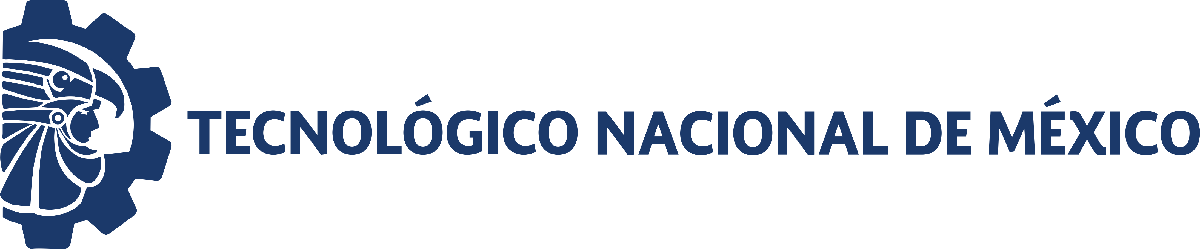                                 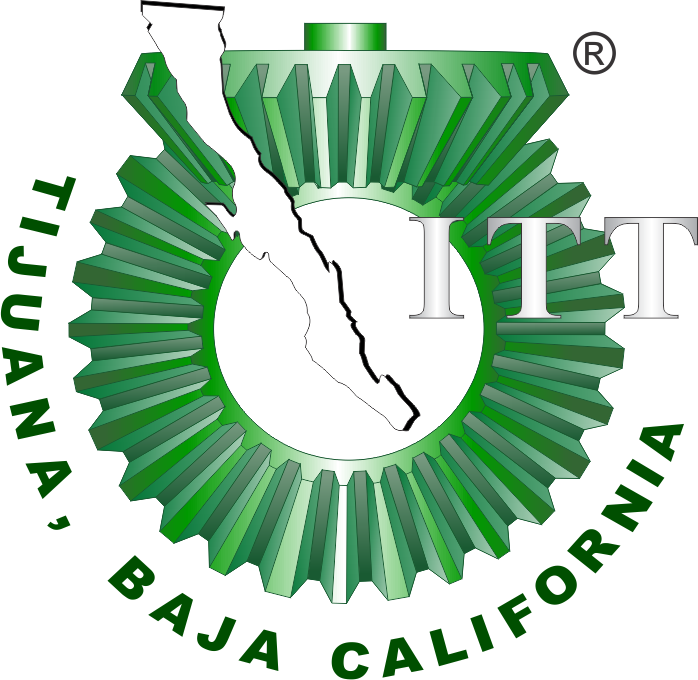

# Práctica 4: Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Bonilla Martinez Nayeli

Número de control: 22212381

Correo institucional: L22212381**@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema3')                
parameters.StopTime = '10';           
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistema3',parameters);      

## Respuesta del sistema:

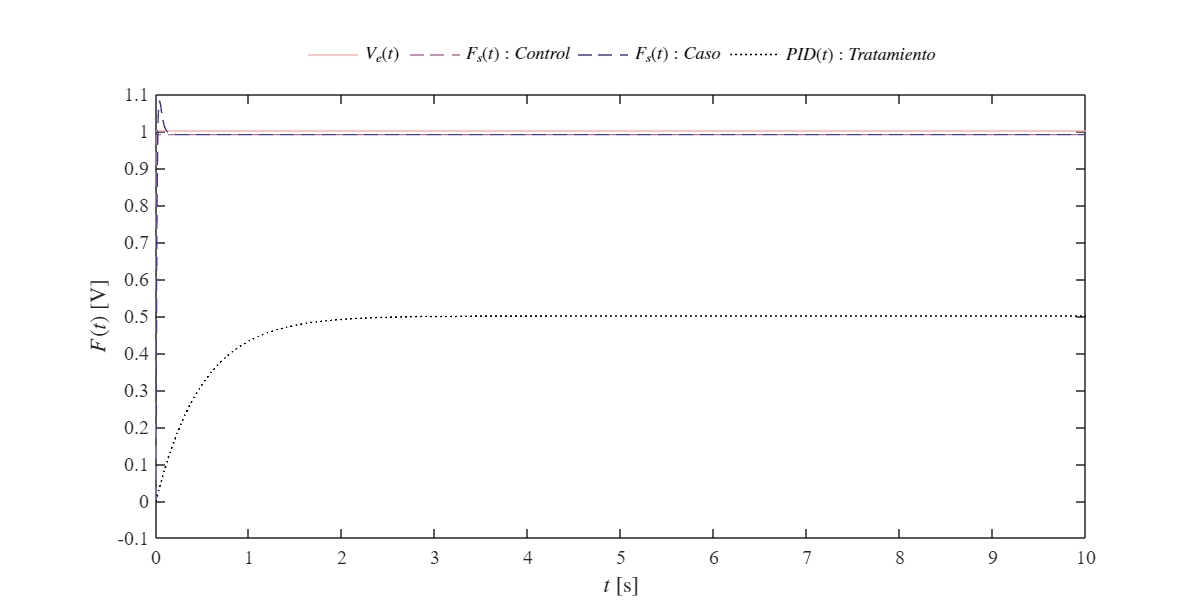

plotsignals(x.t, x.Ve, x.Vs, x.PID, x.Fsy, 'Respuestas')

## Repuesta del sistema

function plotsignals(t,x1,x2,x3,x4,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
    clr1 = [248, 178, 178]/255;
    clr2 = [175, 113, 157]/255;
    clr3 = [64, 61, 136]/255;
    clr4 = [0.5, 0.5, 0.5]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot(t,x1,'-','LineWidth',0.25,'Color',clr1)  %F(t)
    plot(t,x2,'--','LineWidth',0.25,'Color',clr2)  %Control
    plot(t,x3,'--','LineWidth',0.25,'Color',clr3)  %Caso
    plot(t,x4,':','LineWidth',1,'Color',clr4)     %PID Tratamiento
    L = legend('$V_e(t)$','$F_s(t):Control$','$F_s(t):Caso$','$PID(t):Tratamiento$');

set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,[signal,'matlab.pdf'],'ContentType','vector')
end